clc
clear all

## 1. How to import data

To import the data from a document named "brass.csv" which contains strain and stress

data for brass, you can use the following Matlab code:

filename = '/Users/shelton/Downloads/brass.csv';
data = readtable(filename);

% Please replace '/Users/shelton/Downloads/brass.csv' 
% with the actual path where your file is stored.

To extract the three columns of data from the table you imported into Matlab, you can use

the following code:

time = data{3:end, 2};
displacement = data{3:end, 3};
force = data{3:end, 4};

% The data{3:end, 2} will extract all the data from the second column 
% starting from the third row to the last row of the data table.

You can also manually enter data：

width = 12.73;
thickness = 1.52;
length = 78.49;

## 2. How to do calculations

We need to perform a unit conversion. Convert the unit of force from N to kN, and convert

the unit of displacement from mm to inch.

force_kN = force * 0.001;
displacement_inch = displacement * 0.0394;

## 3. How to plot graphs

### 3.1 Line Graph

The command to draw a line graph is plot(), and the set() command can be used to

adjust the style of the graph lines:

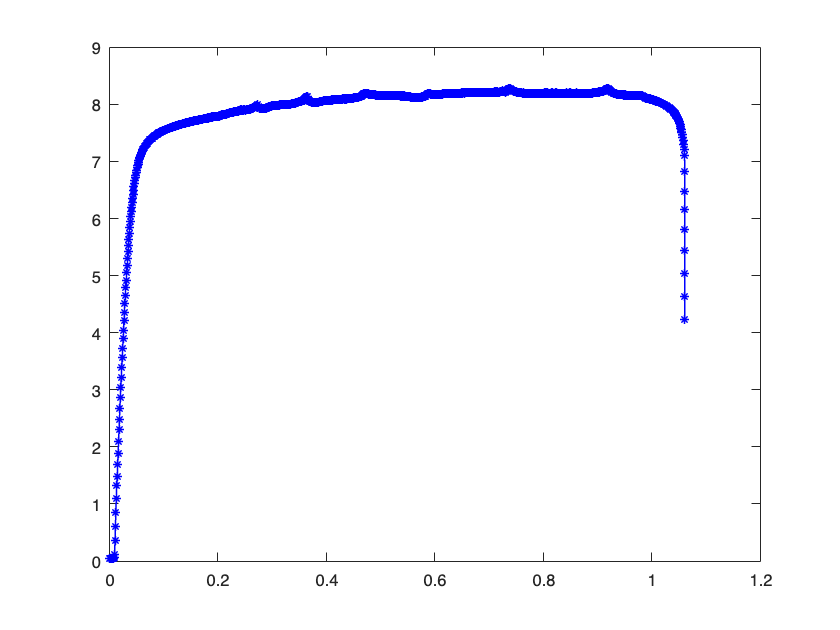

p = plot(displacement_inch, force_kN);
set(p, 'Color', 'blue', 'LineStyle', '-', 'Marker', '*', 'LineWidth', 1);

% In the set() formula, modify properties of the plotting object "p", 
% including "Color", "LineStyle", "Marker", and "LineWidth". 
% For details, see: MATLAB Documentation.

If you need to plot multiple lines on the same graph, enter "hold on", then continue

using the plot() command to draw the second line:

p = plot(displacement_inch, force_kN);
hold on
p1 = plot(0.1 + displacement_inch, force_kN); % Shift the line p to the right by 0.1
p2 = plot(displacement_inch, 0.5 * force_kN); % Halve the amplitude of line p
hold off

Naming the x and y axes:

xlabel('displacement (inch)');
ylabel('force (kN)');

Adjusting the spacing of the x and y axes:

xticks(0:0.1:max(displacement_inch));
yticks(0:2:max(force_kN));

Setting the legend:

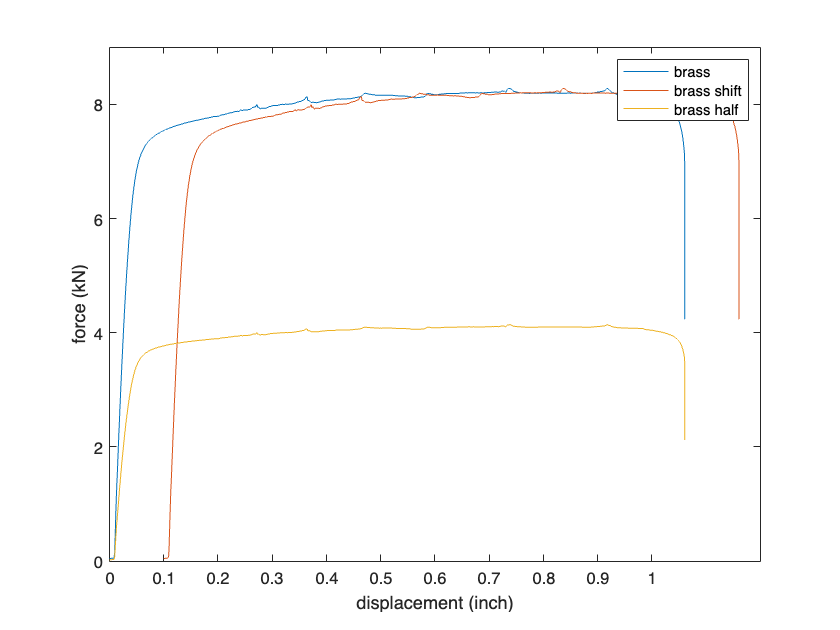

legend('brass'); 
% Only one line needs legend
legend('brass','brass shift','brass half'); 

% Legends are added to the three lines.

Plotting the subplot:

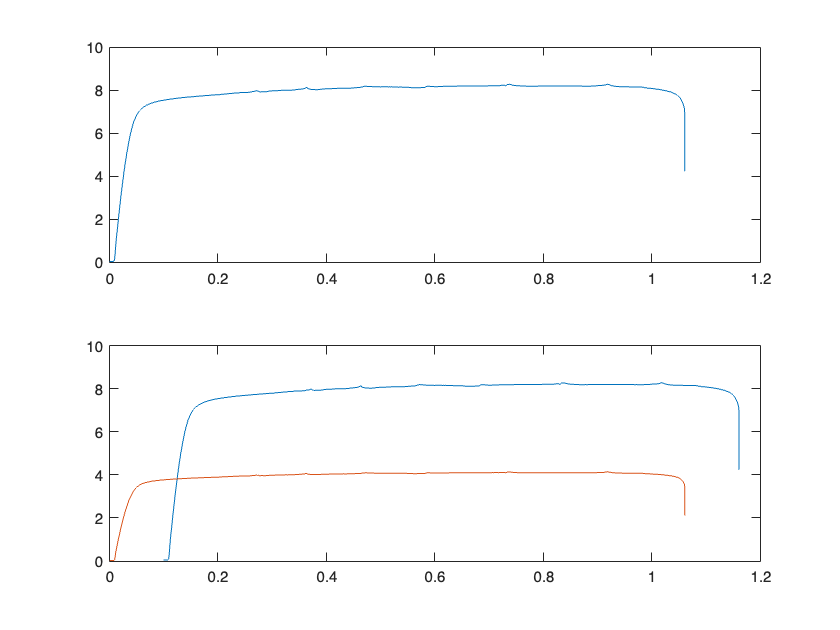

subplot(2, 1, 1);
p = plot(displacement_inch, force_kN);

subplot(2, 1, 2);
p1 = plot(0.1 + displacement_inch, force_kN);
hold on

subplot(2, 1, 2);
p2 = plot(displacement_inch, 0.5 * force_kN);
hold off

% In subplot(2, 1, 1), it means to create a total of 2 plots in a 2 rows * 1 column layout, 
% and to select position 1 for plotting.

### 3.2 Histogram

If we want to analyze the distribution of data, we might need to draw a histogram. Here,

we will use the force data from brass.csv for demonstration.

Similar to plot(), the command for plotting a histogram is histogram(). If we want to divide

the data into 10 equal groups, the command is:

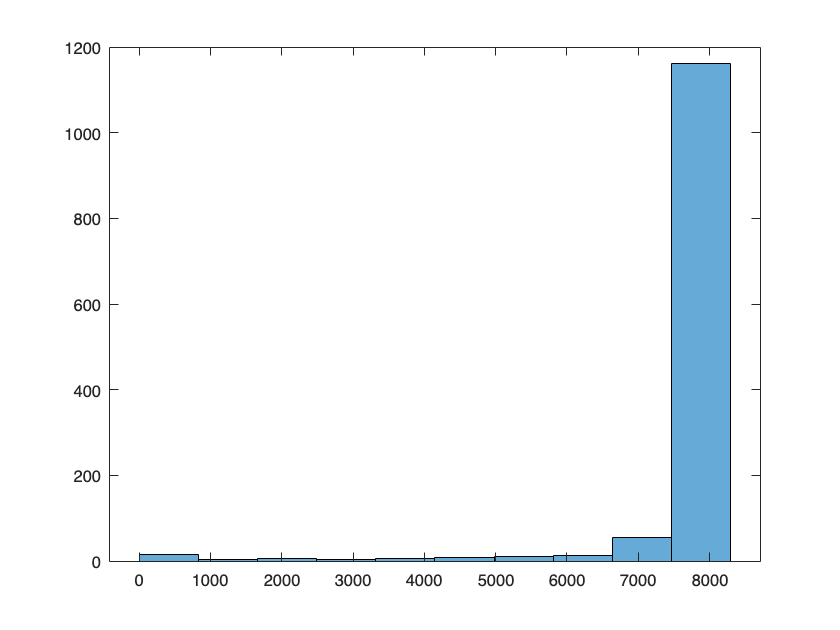

figure;
histogram(force,10);

If you want to customize the boundaries of each group, you need to first set the

boundaries, and then proceed to make the plot:

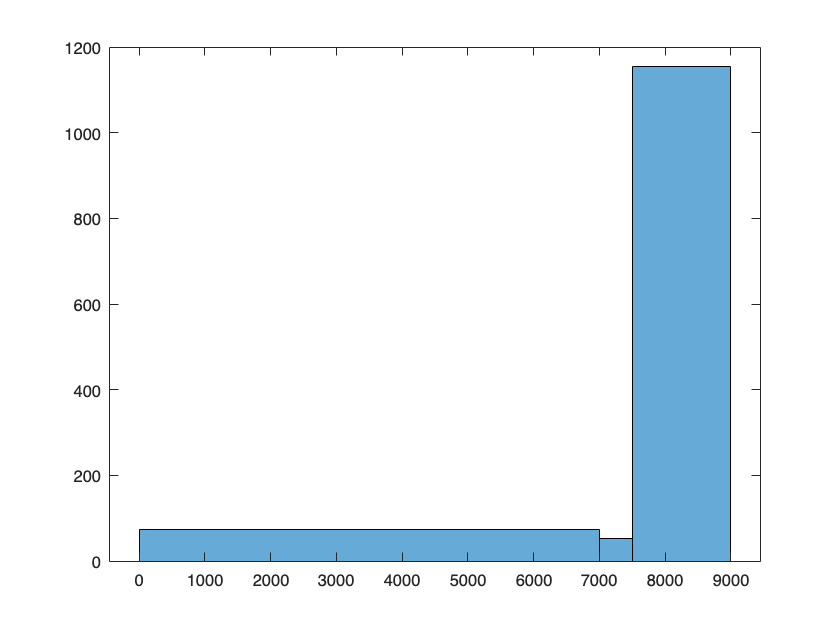

edge = [0, 7000, 7500, 9000];
histogram(force,edge);

## 4. Data statistics

In the figure interface, select **Tools >> Data Statistics** to obtain basic statistical information.